# **Wave Simulations**

For this project, we simulate the temporal representation, spatial representation, and spatial representation at different instants of the optical wave function

$U = Ae^{-(kx-\omega t)^2}$.

Aside from this, we are going to discuss the significance of each wave parameters and we are going to show that U satisfies the differential wave equation 

$\frac{\partial ^2 f}{\partial{x^2}} = \frac{1}{v^2} {\frac{\partial ^2 f}{\partial{t^2}}$.

### Temporal Representation

First, we set the wave constants and temporal parameter.

t = 0:1e-3:1e-1; f = 50; w = 2*pi*f; A = 1;

Then, we simulate the wave.

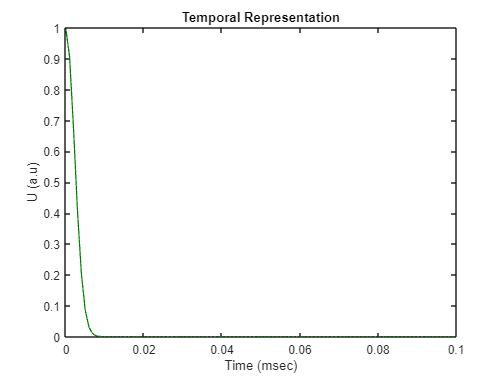

U = A*exp(-(w*t).^2);
figure;
plot(t,U,'LineWidth', 1, 'Color', [0 .5 0]);
title('Temporal Representation');
xlabel('Time (msec)'); ylabel('U (a.u)');

### Spatial Representation

First, we set the wave constants and spatial parameter.

x = -3e-6:1e-8:3e-6; lambda = 1e-6;
k = 2*pi/lambda; A = 1;

Now, we once again simulate the wave.

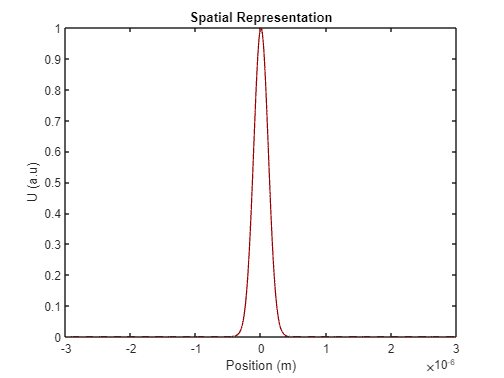

U = A*exp(-(k*x).^2);
figure;
plot(x,U,'LineWidth', 1, 'Color', [.6 0 0]);
title('Spatial Representation');
xlabel('Position (m)'); ylabel('U (a.u)');

### Spatial Representation at Different Instants

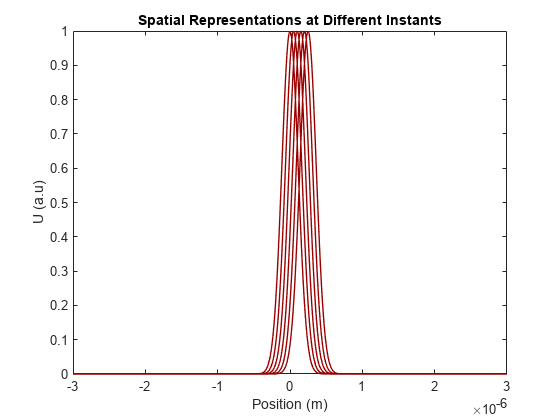

x = -3e-6:1e-8:3e-6; 
lambda = 1e-6; k = 2*pi/lambda; A = 1;
f = 50; w = 2*pi*f;

figure;
for t = 0:1e-3:0.5e-2
    U = A*exp(-(k*x - w*t).^2);
    plot(x, U, 'LineWidth', 1, 'Color', [.6 0 0]);
    colormap gray;
    title('Spatial Representations at Different Instants');
    pause(0.5);
    hold all;
    xlabel('Position (m)');
    ylabel('U (a.u)');
end

### Varying the Parameters

t = 0:1e-3:1e-1; f = 50; w = 2*pi*f; A = 1;
x = -3e-6:1e-8:3e-6; lambda = 1e-6;
k = 2*pi/lambda; A = 1;

**Varying the wave number k**

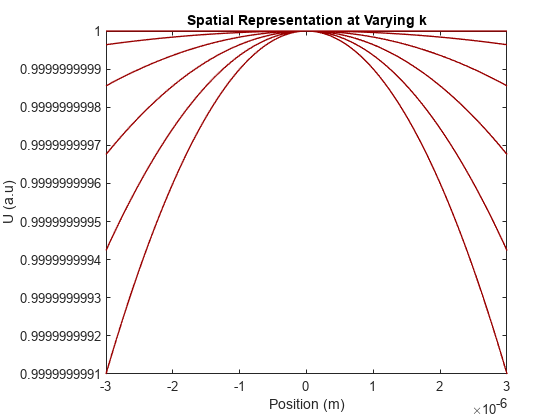

figure;
for k = 0:2:10
    U = A*exp(-(k*x).^2);
    plot(x,U,'LineWidth', 1, 'Color', [.6 0 0]);
    title('Spatial Representation at Varying k');
    xlabel('Position (m)'); ylabel('U (a.u)');
    hold all
end

**Varying the angular velocity w**

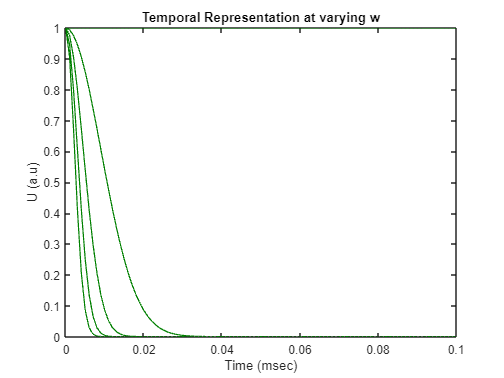

figure;
for w = 0:25*pi:100*pi
    U = A*exp(-(w*t).^2);
    plot(t,U,'LineWidth', 1, 'Color', [0 .5 0]);
    title('Temporal Representation at varying w');
    xlabel('Time (msec)'); ylabel('U (a.u)');
    hold all
end

## **Simulating the Phase Maps**

# Phase maps representing the wavefront

2D unwrapped phase map reveals the curvature or shape of light Optical Physics I, NIP

clear all; close all;
ij=sqrt(-1); %imaginary number
s=512; % array dimension
r=128; % wavefront height factor
a=128; b=1; % tilt
c = 1; d = 1;
A=1; % amplitude
phase_depth=2; % phase depth

## Wavefront (U) with amplitude and phase

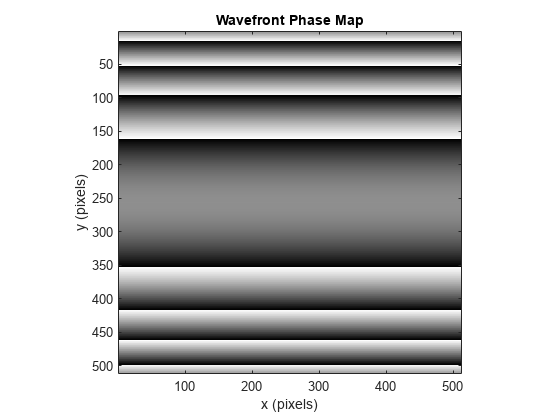

for z=1:1
    [X,Y] = meshgrid(-s/2:s/2-1,-s/2:s/2-1);
    %phase = (X/a) + (Y/b);  %Linear function
    %phase = (r.^2-(X).^2-(Y).^2);  %Spherical function
    %phase = sqrt(r)-sqrt((X).^2+(Y).^2);   %Conical function
    phase = (r.^2-(0).^2-(Y).^2);   %Cylindrical function
    
    phase_ = phase./max(max(phase));
    U=A*exp(ij*(phase_depth*pi*phase_+z*pi/8));  % Wavefront complex field
    ph2=(angle(U));             % Wavefront phase
    
    ph=ph2;  %Display
    figure(1);
    colormap(gray(256));
    mi=min(min(ph));
    ph=ph-mi;
    fact=256/(max(max(ph)));
    image(ph*fact);
    axis square;    pause(0.5)
    title('Wavefront Phase Map'); xlabel('x (pixels)'); ylabel('y (pixels)');
end

## Surface plot of wrapped phase map

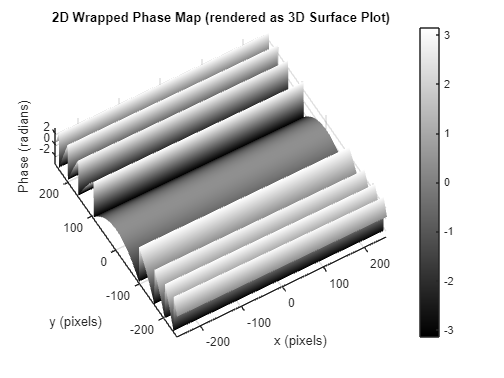

[X,Y] = meshgrid(-s/2:s/2-1,-s/2:s/2-1);
figure %surface plot of the wavefront phase
surf(X,Y,angle(U),'FaceColor','interp', 'EdgeColor','none', 'FaceLighting','phong');
colormap(gray)
view(-30,80),  colorbar, axis tight,
title('2D Wrapped Phase Map (rendered as 3D Surface Plot)'); xlabel('x (pixels)'); ylabel('y (pixels)');zlabel('Phase (radians)');

## Phase Unwrapping (1D)

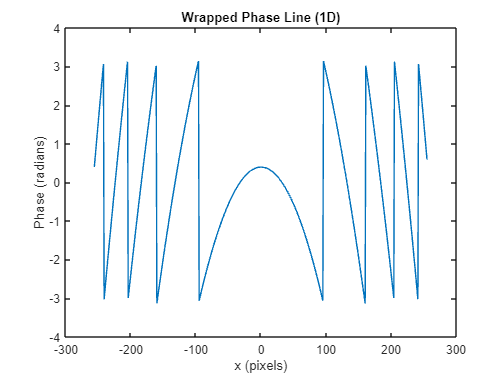

x1=-s/2:s/2-1;

figure %line plot of the wavefront phase, vertical line through the center
plot(x1,angle(U(:,s/2+1))); % angle(z) returns the phase angle in the interval [-π,π] for each element of a complex array z.
title('Wrapped Phase Line (1D)'); xlabel('x (pixels)'); ylabel('Phase (radians)');

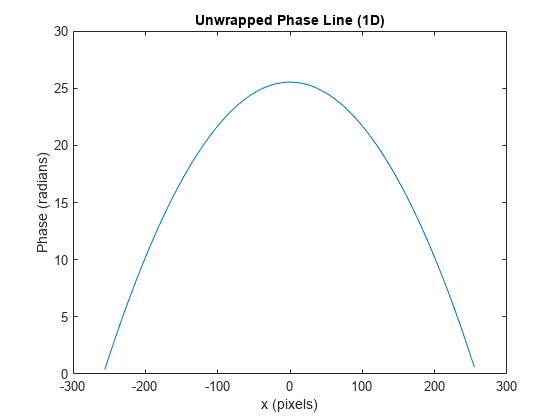


figure %unwrapped phase in 1D
plot(x1,unwrap(angle(U(:,s/2+1))));
title('Unwrapped Phase Line (1D)'); xlabel('x (pixels)'); ylabel('Phase (radians)');

## Phase Unwrapping (2D)

ph_uw = TIE_PUA_iter(angle(U),1); %Phase unwrapping algorithm ***

Iteration no: 1 Error: 1
Iteration no: 2 Error: 453.535
Iteration no: 3 Error: 361.7213
Iteration no: 4 Error: 312.1378
Iteration no: 5 Error: 272.1084
Iteration no: 6 Error: 237.5025
Iteration no: 7 Error: 207.3278
Iteration no: 8 Error: 180.9898
Iteration no: 9 Error: 157.9981
Iteration no: 10 Error: 137.9271
Iteration no: 11 Error: 120.4058
Iteration no: 12 Error: 105.1103
Iteration no: 13 Error: 91.7579
Iteration no: 14 Error: 80.1016
Iteration no: 15 Error: 69.9261
Iteration no: 16 Error: 61.0433
Iteration no: 17 Error: 53.2888
Iteration no: 18 Error: 46.5195
Iteration no: 19 Error: 40.6101
Iteration no: 20 Error: 35.4514
Iteration no: 21 Error: 30.9481
Iteration no: 22 Error: 27.0168
Iteration no: 23 Error: 23.585
Iteration no: 24 Error: 20.5892
Iteration no: 25 Error: 17.9739
Iteration no: 26 Error: 15.6909
Iteration no: 27 Error: 13.698
Iteration no: 28 Error: 11.9583
Iteration no: 29 Error: 10.4396
Iteration no: 30 Error: 9.1139
Iteration no: 31 Error: 7.9567
Iteration no: 32 

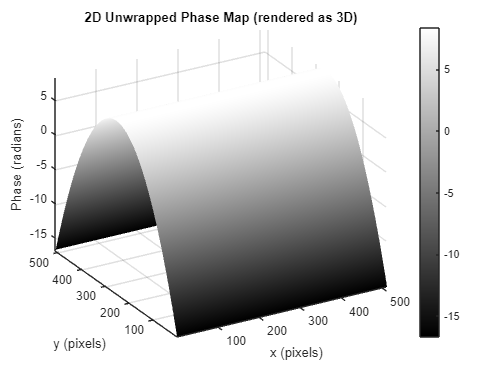

figure %unwrapped phase in 2D
surf(ph_uw,'FaceColor','interp', 'EdgeColor','none', 'FaceLighting','phong');
view(-30,30),  colorbar, axis tight,
colormap(gray)
title('2D Unwrapped Phase Map (rendered as 3D)'); xlabel('x (pixels)'); ylabel('y (pixels)'); zlabel('Phase (radians)');


% %***TIE-PUA-Iterator (Transport of Intensity Equation - Phase Unwrapping
% %Algorithm - Iterator

### Functions

function phase_unwrapped = TIE_PUA(phase_wrapped,dx)
%%%%Initialization%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [M1,N1] = size(phase_wrapped); %pixel dimension MxN
    phase_volkov = padarray(phase_wrapped,[M1 N1],'symmetric','post'); %volkov symmetrization
    [M2,N2] = size(phase_volkov); %pixel dimension MxN
    L = M2*dx; %side length
    fx = -1/(2*dx):1/L:1/(2*dx)-1/L;
    [Fx,Fy] = meshgrid(fx,fx); %fourier space grid
%%%%TIE-PUA%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    psi = exp(1i*phase_volkov);%auxillary function
    D = fftshift(Fx.^2+Fy.^2); %squared sum fourier coords
    ep = 1e-5; %small number to avoid division by zero
    Fg = D.*fft2(fftshift(psi));
    lap = ifftshift(ifft2(Fg));
    im_arg = conj(psi).*lap;
    diff_dz = fftshift(imag(im_arg)); %longitudinal derivative
    phase_unwrapped = ifftshift(ifft2(D.*fft2(diff_dz)./(D.^2+ep.^2)));
    phase_unwrapped = real(phase_unwrapped); %neglect imag part
    phase_unwrapped = phase_unwrapped(1:M1,1:N1); %crop top left window 
end

function [phase_unwrapped,err_vec] = TIE_PUA_iter(phase_wrapped,dx)
    phi_uw = TIE_PUA(phase_wrapped,dx); 
%%%%Initializations
    phi_uw_i = phi_uw;
%     tol = eps*1000; %set tolerance (4 orders higher than machine epsilon)
    tol = 0.6;
    c = 1; %set counter
    err = 1; %set initial error;
    err_i = 1;
while err_i > tol
    disp(['Iteration no: ', num2str(c), ' Error: ', num2str(err(c))]);
    phi_w_i = wrapToPi(phi_uw_i); %re-wrap unwrapped phase
    del_ph_i = phase_wrapped-phi_w_i; %subtract to original wrapped phase
    mean_del = mean2(del_ph_i); %piston term
    del_phi_i = wrapToPi(del_ph_i-mean_del); %wrapped correction term
    del_phi_c = TIE_PUA(del_phi_i,dx); %unwrapped correction term
    phi_uw_i = phi_uw_i + del_phi_c;
    err_i = sqrt(sum(sum(del_phi_c.^2)));
    err = [err; err_i];
    c = c + 1;
end 
phase_unwrapped = phi_uw_i;
err_vec = err;
end